% List of test files (Healthy + Anomalous)
allsvmAudioFiles = [audioFiles, abnormalaudioFiles]; % Combine normal and test sets
numTotalFilessvm = length(allsvmAudioFiles);

% Feature Storage
allsvmFeatures = [];
allLabelssvm = [];

for i = 1:numTotalFilessvm
    fileName = allsvmAudioFiles(i);

    % Extract Features
    timeFreqFeaturessvm = generateAudioFeatures(fileName, 1); % Extract time/freq features
    fftFeaturessvm = generateFFTFeatures(fileName, 1, 1024);  % Extract FFT features

    % Convert tables to arrays and concatenate
    featureVectorsvm = [table2array(timeFreqFeaturessvm), table2array(fftFeaturessvm)];

    % Store Features
    allsvmFeatures = [allsvmFeatures; featureVectorsvm];

    % Assign Labels: Healthy (0) for waveformData, Anomalous (1) for testwaveformData
    if ismember(fileName, audioFiles)
        allLabelssvm = [allLabelssvm; 0]; % Healthy
    else
        allLabelssvm = [allLabelssvm; 1]; % Anomalous
    end
end

% Convert to Table
featureNamesvm = [timeFreqFeaturessvm.Properties.VariableNames, fftFeaturessvm.Properties.VariableNames];
featureTablesvm = array2table(allsvmFeatures, 'VariableNames', featureNamesvm);
featureTablesvm.Label = allLabelssvm;
disp(featureTablesvm);

           RMS            ZeroCrossRate    SpectralCentroid          MFCC1                MFCC2               MFCC3                 MFCC4                   MFCC5                  MFCC6                  MFCC7                  MFCC8                  MFCC9                 MFCC10                 MFCC11                 MFCC12                  MFCC13                  MFCC14               MaxFreqMag          MeanFreqMag         MedianFreqMag       DominantFreq    Label
    __________________    _____________    ________________    _________________    

SVM Accuracy: 100.00%
SVM Accuracy: 50.00%
SVM Accuracy: 83.33%
SVM Accuracy: 87.50%
SVM Accuracy: 90.00%
SVM Accuracy: 91.67%
SVM Accuracy: 85.71%
SVM Accuracy: 81.25%
SVM Accuracy: 83.33%


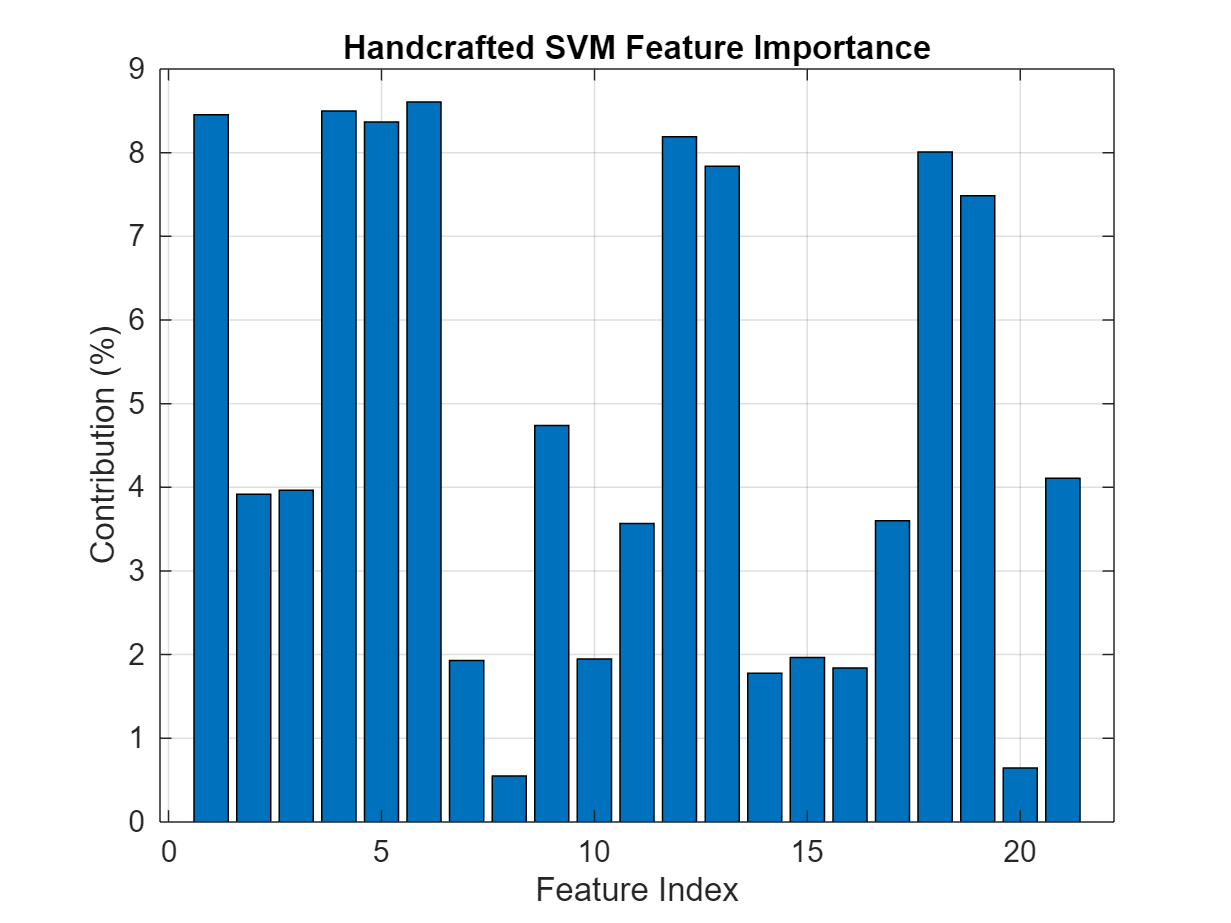


% Convert features to a numeric matrix
featureMatrixsvm = table2array(featureTablesvm(:, 1:end-1));
labelsvm = featureTablesvm.Label;

perfMod = 0.9; performanceMatrixdisplaySVM = zeros(9,1);

for perfModiter = 0.1:0.1:perfMod
    % Split Data 
    cv = cvpartition(labelsvm, 'HoldOut', perfModiter);
    XTrain = featureMatrixsvm(training(cv), :);
    YTrain = labelsvm(training(cv));
    XTest = featureMatrixsvm(test(cv), :);
    YTest = labelsvm(test(cv));
    
    % Train SVM Model
    svmModel = fitcsvm(XTrain, YTrain, 'KernelFunction', 'linear', 'Standardize', true);
    
    % Predict on Test Data
    YPred = predict(svmModel, XTest);
    
    % Accuracy
    accuracy = sum(YPred == YTest) / length(YTest);
    fprintf('SVM Accuracy: %.2f%%\n', accuracy * 100);

    % Confusion Matrix
    confusionchart(YTest, YPred);
    title('SVM Confusion Matrix');
    
    svmWeights = svmModel.Beta;
    featureContributionsvm = abs(svmWeights) / sum(abs(svmWeights)) * 100;
    bar(featureContributionsvm);
    xlabel('Feature Index');
    ylabel('Contribution (%)');
    title('Handcrafted SVM Feature Importance');
    grid on;
end